x = 25;
y = 1000;
z = 0;

EnergyBalanceModelArctic(z/273.15 + 1, x, 104, y, 0.6)

ans = 0.0771

% ALL CODE IN THIS SCRIPT IS ADAPTED FROM THE CODEBASE OF
% K. L. Kypke, W. F. Langford, and A. R. Willms. Anthropocene climate bifurcation. Nonlinear processes in geophysics, 27(3):391–409, 2020.

options = optimset('Display','off');

% Compute current day temperature in Arctic
presentclimArc = fsolve(@(tau) EnergyBalanceModelArctic(tau, 9.75, 104, 400, 0.6), 0.9, options);

% Load CO2 data for different shared socioeconomic pathways
CO285data = [2.78E+02	2.78E+02	2.78E+02	2.78E+02	2.78E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.80E+02	2.80E+02	2.80E+02	2.80E+02	2.80E+02	2.80E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.86E+02	2.86E+02	2.86E+02	2.86E+02	2.86E+02	2.86E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.88E+02	2.88E+02	2.88E+02	2.88E+02	2.88E+02	2.89E+02	2.89E+02	2.89E+02	2.90E+02	2.90E+02	2.91E+02	2.91E+02	2.92E+02	2.92E+02	2.93E+02	2.93E+02	2.93E+02	2.94E+02	2.94E+02	2.94E+02	2.94E+02	2.94E+02	2.94E+02	2.95E+02	2.95E+02	2.95E+02	2.95E+02	2.95E+02	2.95E+02	2.96E+02	2.96E+02	2.96E+02	2.96E+02	2.97E+02	2.97E+02	2.98E+02	2.98E+02	2.99E+02	2.99E+02	2.99E+02	3.00E+02	3.00E+02	3.00E+02	3.01E+02	3.01E+02	3.01E+02	3.02E+02	3.02E+02	3.02E+02	3.03E+02	3.03E+02	3.03E+02	3.04E+02	3.04E+02	3.05E+02	3.05E+02	3.05E+02	3.06E+02	3.06E+02	3.07E+02	3.07E+02	3.08E+02	3.08E+02	3.09E+02	3.09E+02	3.09E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.11E+02	3.11E+02	3.11E+02	3.12E+02	3.12E+02	3.12E+02	3.13E+02	3.14E+02	3.14E+02	3.15E+02	3.16E+02	3.16E+02	3.17E+02	3.18E+02	3.18E+02	3.19E+02	3.20E+02	3.21E+02	3.22E+02	3.23E+02	3.24E+02	3.25E+02	3.26E+02	3.27E+02	3.29E+02	3.30E+02	3.31E+02	3.32E+02	3.33E+02	3.35E+02	3.37E+02	3.38E+02	3.40E+02	3.41E+02	3.42E+02	3.44E+02	3.45E+02	3.47E+02	3.49E+02	3.51E+02	3.52E+02	3.54E+02	3.55E+02	3.56E+02	3.57E+02	3.58E+02	3.60E+02	3.61E+02	3.63E+02	3.65E+02	3.67E+02	3.69E+02	3.70E+02	3.73E+02	3.75E+02	3.77E+02	3.79E+02	3.81E+02	3.83E+02	3.85E+02	3.87E+02	3.89E+02	3.92E+02	3.94E+02	3.96E+02	3.99E+02	4.02E+02	4.04E+02	4.07E+02	4.10E+02	4.13E+02	4.16E+02	4.19E+02	4.22E+02	4.25E+02	4.28E+02	4.31E+02	4.35E+02	4.38E+02	4.42E+02	4.45E+02	4.49E+02	4.52E+02	4.56E+02	4.60E+02	4.64E+02	4.68E+02	4.72E+02	4.76E+02	4.81E+02	4.85E+02	4.89E+02	4.94E+02	4.99E+02	5.04E+02	5.08E+02	5.13E+02	5.19E+02	5.24E+02	5.29E+02	5.35E+02	5.41E+02	5.46E+02	5.52E+02	5.58E+02	5.64E+02	5.71E+02	5.77E+02	5.83E+02	5.90E+02	5.97E+02	6.04E+02	6.11E+02	6.18E+02	6.25E+02	6.32E+02	6.39E+02	6.47E+02	6.54E+02	6.62E+02	6.69E+02	6.77E+02	6.85E+02	6.93E+02	7.01E+02	7.09E+02	7.17E+02	7.25E+02	7.33E+02	7.42E+02	7.50E+02	7.58E+02	7.67E+02	7.75E+02	7.84E+02	7.92E+02	8.01E+02	8.10E+02	8.18E+02	8.27E+02	8.36E+02	8.45E+02	8.54E+02	8.63E+02	8.72E+02	8.81E+02	8.90E+02	8.99E+02	9.08E+02	9.17E+02	9.27E+02	9.36E+02	9.45E+02	9.54E+02	9.64E+02	9.73E+02	9.83E+02	9.92E+02	1.00E+03	1.01E+03	1.02E+03	1.03E+03	1.04E+03	1.05E+03	1.06E+03	1.07E+03	1.08E+03	1.09E+03	1.10E+03	1.11E+03	1.12E+03	1.13E+03	1.14E+03	1.15E+03	1.16E+03	1.17E+03	1.18E+03	1.19E+03	1.20E+03	1.21E+03	1.22E+03	1.23E+03	1.24E+03	1.25E+03	1.26E+03	1.27E+03	1.28E+03	1.29E+03	1.30E+03	1.31E+03	1.32E+03	1.33E+03	1.34E+03	1.35E+03	1.36E+03	1.37E+03	1.38E+03	1.39E+03	1.40E+03	1.41E+03	1.42E+03	1.43E+03	1.44E+03	1.45E+03	1.46E+03	1.47E+03	1.48E+03	1.49E+03	1.50E+03	1.51E+03	1.52E+03	1.53E+03	1.54E+03	1.55E+03	1.56E+03	1.57E+03	1.58E+03	1.58E+03	1.59E+03	1.60E+03	1.61E+03	1.62E+03	1.63E+03	1.64E+03	1.64E+03	1.65E+03	1.66E+03	1.67E+03	1.68E+03	1.68E+03	1.69E+03	1.70E+03	1.71E+03	1.71E+03	1.72E+03	1.73E+03	1.74E+03	1.74E+03	1.75E+03	1.76E+03	1.76E+03	1.77E+03	1.78E+03	1.78E+03	1.79E+03	1.79E+03	1.80E+03	1.81E+03	1.81E+03	1.82E+03	1.82E+03	1.83E+03	1.83E+03	1.84E+03	1.84E+03	1.85E+03	1.85E+03	1.86E+03	1.86E+03	1.87E+03	1.87E+03	1.88E+03	1.88E+03	1.89E+03	1.89E+03	1.89E+03	1.90E+03	1.90E+03	1.91E+03	1.91E+03	1.91E+03	1.92E+03	1.92E+03	1.92E+03	1.92E+03	1.93E+03	1.93E+03	1.93E+03	1.94E+03	1.94E+03	1.94E+03	1.94E+03	1.94E+03	1.95E+03	1.95E+03	1.95E+03	1.95E+03	1.95E+03	1.95E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03	1.96E+03];
CO260data = [2.78E+02	2.78E+02	2.78E+02	2.78E+02	2.78E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.80E+02	2.80E+02	2.80E+02	2.80E+02	2.80E+02	2.80E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.86E+02	2.86E+02	2.86E+02	2.86E+02	2.86E+02	2.86E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.88E+02	2.88E+02	2.88E+02	2.88E+02	2.88E+02	2.89E+02	2.89E+02	2.89E+02	2.90E+02	2.90E+02	2.91E+02	2.91E+02	2.92E+02	2.92E+02	2.93E+02	2.93E+02	2.93E+02	2.94E+02	2.94E+02	2.94E+02	2.94E+02	2.94E+02	2.94E+02	2.95E+02	2.95E+02	2.95E+02	2.95E+02	2.95E+02	2.95E+02	2.96E+02	2.96E+02	2.96E+02	2.96E+02	2.97E+02	2.97E+02	2.98E+02	2.98E+02	2.99E+02	2.99E+02	2.99E+02	3.00E+02	3.00E+02	3.00E+02	3.01E+02	3.01E+02	3.01E+02	3.02E+02	3.02E+02	3.02E+02	3.03E+02	3.03E+02	3.03E+02	3.04E+02	3.04E+02	3.05E+02	3.05E+02	3.05E+02	3.06E+02	3.06E+02	3.07E+02	3.07E+02	3.08E+02	3.08E+02	3.09E+02	3.09E+02	3.09E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.11E+02	3.11E+02	3.11E+02	3.12E+02	3.12E+02	3.12E+02	3.13E+02	3.14E+02	3.14E+02	3.15E+02	3.16E+02	3.16E+02	3.17E+02	3.18E+02	3.18E+02	3.19E+02	3.20E+02	3.21E+02	3.22E+02	3.23E+02	3.24E+02	3.25E+02	3.26E+02	3.27E+02	3.29E+02	3.30E+02	3.31E+02	3.32E+02	3.33E+02	3.35E+02	3.37E+02	3.38E+02	3.40E+02	3.41E+02	3.42E+02	3.44E+02	3.45E+02	3.47E+02	3.49E+02	3.51E+02	3.52E+02	3.54E+02	3.55E+02	3.56E+02	3.57E+02	3.58E+02	3.60E+02	3.61E+02	3.63E+02	3.65E+02	3.67E+02	3.69E+02	3.70E+02	3.73E+02	3.75E+02	3.77E+02	3.79E+02	3.81E+02	3.83E+02	3.85E+02	3.87E+02	3.89E+02	3.91E+02	3.93E+02	3.95E+02	3.97E+02	3.99E+02	4.01E+02	4.03E+02	4.05E+02	4.07E+02	4.09E+02	4.11E+02	4.13E+02	4.15E+02	4.17E+02	4.19E+02	4.21E+02	4.23E+02	4.25E+02	4.27E+02	4.29E+02	4.31E+02	4.33E+02	4.35E+02	4.37E+02	4.39E+02	4.41E+02	4.44E+02	4.46E+02	4.48E+02	4.51E+02	4.53E+02	4.56E+02	4.58E+02	4.61E+02	4.63E+02	4.66E+02	4.69E+02	4.72E+02	4.75E+02	4.78E+02	4.81E+02	4.84E+02	4.87E+02	4.90E+02	4.93E+02	4.97E+02	5.00E+02	5.03E+02	5.07E+02	5.11E+02	5.14E+02	5.18E+02	5.22E+02	5.26E+02	5.29E+02	5.33E+02	5.37E+02	5.41E+02	5.46E+02	5.50E+02	5.54E+02	5.58E+02	5.63E+02	5.67E+02	5.72E+02	5.76E+02	5.81E+02	5.85E+02	5.90E+02	5.94E+02	5.99E+02	6.04E+02	6.08E+02	6.12E+02	6.17E+02	6.21E+02	6.25E+02	6.28E+02	6.32E+02	6.36E+02	6.39E+02	6.43E+02	6.46E+02	6.50E+02	6.53E+02	6.56E+02	6.60E+02	6.63E+02	6.66E+02	6.70E+02	6.73E+02	6.76E+02	6.80E+02	6.83E+02	6.86E+02	6.89E+02	6.92E+02	6.94E+02	6.97E+02	7.00E+02	7.02E+02	7.05E+02	7.07E+02	7.10E+02	7.12E+02	7.14E+02	7.16E+02	7.19E+02	7.21E+02	7.23E+02	7.24E+02	7.26E+02	7.28E+02	7.30E+02	7.31E+02	7.33E+02	7.34E+02	7.36E+02	7.37E+02	7.39E+02	7.40E+02	7.41E+02	7.42E+02	7.43E+02	7.44E+02	7.45E+02	7.46E+02	7.47E+02	7.48E+02	7.48E+02	7.49E+02	7.50E+02	7.50E+02	7.51E+02	7.51E+02	7.51E+02	7.51E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02	7.52E+02];
CO245data = [2.78E+02	2.78E+02	2.78E+02	2.78E+02	2.78E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.80E+02	2.80E+02	2.80E+02	2.80E+02	2.80E+02	2.80E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.86E+02	2.86E+02	2.86E+02	2.86E+02	2.86E+02	2.86E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.88E+02	2.88E+02	2.88E+02	2.88E+02	2.88E+02	2.89E+02	2.89E+02	2.89E+02	2.90E+02	2.90E+02	2.91E+02	2.91E+02	2.92E+02	2.92E+02	2.93E+02	2.93E+02	2.93E+02	2.94E+02	2.94E+02	2.94E+02	2.94E+02	2.94E+02	2.94E+02	2.95E+02	2.95E+02	2.95E+02	2.95E+02	2.95E+02	2.95E+02	2.96E+02	2.96E+02	2.96E+02	2.96E+02	2.97E+02	2.97E+02	2.98E+02	2.98E+02	2.99E+02	2.99E+02	2.99E+02	3.00E+02	3.00E+02	3.00E+02	3.01E+02	3.01E+02	3.01E+02	3.02E+02	3.02E+02	3.02E+02	3.03E+02	3.03E+02	3.03E+02	3.04E+02	3.04E+02	3.05E+02	3.05E+02	3.05E+02	3.06E+02	3.06E+02	3.07E+02	3.07E+02	3.08E+02	3.08E+02	3.09E+02	3.09E+02	3.09E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.11E+02	3.11E+02	3.11E+02	3.12E+02	3.12E+02	3.12E+02	3.13E+02	3.14E+02	3.14E+02	3.15E+02	3.16E+02	3.16E+02	3.17E+02	3.18E+02	3.18E+02	3.19E+02	3.20E+02	3.21E+02	3.22E+02	3.23E+02	3.24E+02	3.25E+02	3.26E+02	3.27E+02	3.29E+02	3.30E+02	3.31E+02	3.32E+02	3.33E+02	3.35E+02	3.37E+02	3.38E+02	3.40E+02	3.41E+02	3.42E+02	3.44E+02	3.45E+02	3.47E+02	3.49E+02	3.51E+02	3.52E+02	3.54E+02	3.55E+02	3.56E+02	3.57E+02	3.58E+02	3.60E+02	3.61E+02	3.63E+02	3.65E+02	3.67E+02	3.69E+02	3.70E+02	3.73E+02	3.75E+02	3.77E+02	3.79E+02	3.81E+02	3.83E+02	3.85E+02	3.87E+02	3.89E+02	3.91E+02	3.93E+02	3.96E+02	3.98E+02	4.00E+02	4.02E+02	4.04E+02	4.07E+02	4.09E+02	4.11E+02	4.13E+02	4.16E+02	4.18E+02	4.20E+02	4.23E+02	4.25E+02	4.28E+02	4.30E+02	4.33E+02	4.35E+02	4.38E+02	4.40E+02	4.43E+02	4.45E+02	4.48E+02	4.50E+02	4.53E+02	4.56E+02	4.58E+02	4.61E+02	4.63E+02	4.66E+02	4.69E+02	4.71E+02	4.74E+02	4.76E+02	4.79E+02	4.81E+02	4.84E+02	4.87E+02	4.89E+02	4.92E+02	4.94E+02	4.96E+02	4.98E+02	5.01E+02	5.03E+02	5.05E+02	5.07E+02	5.09E+02	5.11E+02	5.13E+02	5.14E+02	5.16E+02	5.18E+02	5.19E+02	5.20E+02	5.22E+02	5.23E+02	5.24E+02	5.25E+02	5.27E+02	5.27E+02	5.28E+02	5.29E+02	5.30E+02	5.30E+02	5.31E+02	5.31E+02	5.31E+02	5.31E+02	5.31E+02	5.32E+02	5.32E+02	5.32E+02	5.32E+02	5.33E+02	5.33E+02	5.33E+02	5.34E+02	5.34E+02	5.35E+02	5.35E+02	5.35E+02	5.36E+02	5.36E+02	5.37E+02	5.37E+02	5.38E+02	5.38E+02	5.39E+02	5.39E+02	5.40E+02	5.40E+02	5.41E+02	5.41E+02	5.42E+02	5.42E+02	5.42E+02	5.42E+02	5.42E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02	5.43E+02];
CO225data = [2.78E+02	2.78E+02	2.78E+02	2.78E+02	2.78E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.79E+02	2.80E+02	2.80E+02	2.80E+02	2.80E+02	2.80E+02	2.80E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.81E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.82E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.83E+02	2.83E+02	2.83E+02	2.83E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.84E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.85E+02	2.86E+02	2.86E+02	2.86E+02	2.86E+02	2.86E+02	2.86E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.87E+02	2.88E+02	2.88E+02	2.88E+02	2.88E+02	2.88E+02	2.89E+02	2.89E+02	2.89E+02	2.90E+02	2.90E+02	2.91E+02	2.91E+02	2.92E+02	2.92E+02	2.93E+02	2.93E+02	2.93E+02	2.94E+02	2.94E+02	2.94E+02	2.94E+02	2.94E+02	2.94E+02	2.95E+02	2.95E+02	2.95E+02	2.95E+02	2.95E+02	2.95E+02	2.96E+02	2.96E+02	2.96E+02	2.96E+02	2.97E+02	2.97E+02	2.98E+02	2.98E+02	2.99E+02	2.99E+02	2.99E+02	3.00E+02	3.00E+02	3.00E+02	3.01E+02	3.01E+02	3.01E+02	3.02E+02	3.02E+02	3.02E+02	3.03E+02	3.03E+02	3.03E+02	3.04E+02	3.04E+02	3.05E+02	3.05E+02	3.05E+02	3.06E+02	3.06E+02	3.07E+02	3.07E+02	3.08E+02	3.08E+02	3.09E+02	3.09E+02	3.09E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.10E+02	3.11E+02	3.11E+02	3.11E+02	3.12E+02	3.12E+02	3.12E+02	3.13E+02	3.14E+02	3.14E+02	3.15E+02	3.16E+02	3.16E+02	3.17E+02	3.18E+02	3.18E+02	3.19E+02	3.20E+02	3.21E+02	3.22E+02	3.23E+02	3.24E+02	3.25E+02	3.26E+02	3.27E+02	3.29E+02	3.30E+02	3.31E+02	3.32E+02	3.33E+02	3.35E+02	3.37E+02	3.38E+02	3.40E+02	3.41E+02	3.42E+02	3.44E+02	3.45E+02	3.47E+02	3.49E+02	3.51E+02	3.52E+02	3.54E+02	3.55E+02	3.56E+02	3.57E+02	3.58E+02	3.60E+02	3.61E+02	3.63E+02	3.65E+02	3.67E+02	3.69E+02	3.70E+02	3.73E+02	3.75E+02	3.77E+02	3.79E+02	3.81E+02	3.83E+02	3.85E+02	3.87E+02	3.89E+02	3.92E+02	3.94E+02	3.96E+02	3.98E+02	4.01E+02	4.03E+02	4.05E+02	4.08E+02	4.10E+02	4.12E+02	4.14E+02	4.17E+02	4.19E+02	4.21E+02	4.23E+02	4.24E+02	4.26E+02	4.28E+02	4.29E+02	4.31E+02	4.32E+02	4.33E+02	4.35E+02	4.36E+02	4.37E+02	4.38E+02	4.38E+02	4.39E+02	4.40E+02	4.40E+02	4.41E+02	4.41E+02	4.41E+02	4.42E+02	4.42E+02	4.42E+02	4.42E+02	4.42E+02	4.43E+02	4.43E+02	4.43E+02	4.43E+02	4.43E+02	4.43E+02	4.43E+02	4.42E+02	4.42E+02	4.42E+02	4.42E+02	4.42E+02	4.41E+02	4.41E+02	4.41E+02	4.40E+02	4.40E+02	4.40E+02	4.39E+02	4.39E+02	4.38E+02	4.37E+02	4.37E+02	4.36E+02	4.36E+02	4.35E+02	4.35E+02	4.34E+02	4.33E+02	4.33E+02	4.32E+02	4.32E+02	4.31E+02	4.31E+02	4.30E+02	4.29E+02	4.29E+02	4.28E+02	4.28E+02	4.27E+02	4.27E+02	4.26E+02	4.25E+02	4.25E+02	4.24E+02	4.24E+02	4.23E+02	4.23E+02	4.22E+02	4.22E+02	4.21E+02	4.21E+02	4.20E+02	4.20E+02	4.19E+02	4.19E+02	4.19E+02	4.18E+02	4.18E+02	4.17E+02	4.17E+02	4.16E+02	4.16E+02	4.15E+02	4.15E+02	4.14E+02	4.14E+02	4.14E+02	4.13E+02	4.13E+02	4.12E+02	4.12E+02	4.11E+02	4.11E+02	4.10E+02	4.10E+02	4.09E+02	4.09E+02	4.08E+02	4.08E+02	4.08E+02	4.07E+02	4.07E+02	4.06E+02	4.06E+02	4.05E+02	4.05E+02	4.04E+02	4.04E+02	4.04E+02	4.03E+02	4.03E+02	4.03E+02	4.02E+02	4.02E+02	4.01E+02	4.01E+02	4.01E+02	4.00E+02	4.00E+02	3.99E+02	3.99E+02	3.99E+02	3.98E+02	3.98E+02	3.98E+02	3.97E+02	3.97E+02	3.97E+02	3.96E+02	3.96E+02	3.96E+02	3.95E+02	3.95E+02	3.95E+02	3.94E+02	3.94E+02	3.94E+02	3.93E+02	3.93E+02	3.93E+02	3.92E+02	3.92E+02	3.92E+02	3.92E+02	3.91E+02	3.91E+02	3.91E+02	3.90E+02	3.90E+02	3.90E+02	3.89E+02	3.89E+02	3.89E+02	3.89E+02	3.88E+02	3.88E+02	3.88E+02	3.87E+02	3.87E+02	3.87E+02	3.86E+02	3.86E+02	3.86E+02	3.86E+02	3.85E+02	3.85E+02	3.85E+02	3.85E+02	3.84E+02	3.84E+02	3.84E+02	3.83E+02	3.83E+02	3.83E+02	3.83E+02	3.82E+02	3.82E+02	3.82E+02	3.82E+02	3.81E+02	3.81E+02	3.81E+02	3.81E+02	3.80E+02	3.80E+02	3.80E+02	3.80E+02	3.79E+02	3.79E+02	3.79E+02	3.79E+02	3.78E+02	3.78E+02	3.78E+02	3.78E+02	3.77E+02	3.77E+02	3.77E+02	3.77E+02	3.76E+02	3.76E+02	3.76E+02	3.76E+02	3.75E+02	3.75E+02	3.75E+02	3.75E+02	3.74E+02	3.74E+02	3.74E+02	3.74E+02	3.74E+02	3.73E+02	3.73E+02	3.73E+02	3.73E+02	3.72E+02	3.72E+02	3.72E+02	3.72E+02	3.71E+02	3.71E+02	3.71E+02	3.71E+02	3.70E+02	3.70E+02	3.70E+02	3.70E+02	3.70E+02	3.69E+02	3.69E+02	3.69E+02	3.69E+02	3.69E+02	3.68E+02	3.68E+02	3.68E+02	3.68E+02	3.67E+02	3.67E+02	3.67E+02	3.67E+02	3.67E+02	3.66E+02	3.66E+02	3.66E+02	3.66E+02	3.65E+02	3.65E+02	3.65E+02	3.65E+02	3.65E+02	3.64E+02	3.64E+02	3.64E+02	3.64E+02	3.64E+02	3.63E+02	3.63E+02	3.63E+02	3.63E+02	3.63E+02	3.62E+02	3.62E+02	3.62E+02	3.62E+02	3.62E+02	3.61E+02	3.61E+02	3.61E+02	3.61E+02	3.60E+02	3.60E+02	3.60E+02	3.60E+02	3.60E+02	3.60E+02	3.59E+02	3.59E+02	3.59E+02	3.59E+02	3.58E+02	3.58E+02	3.58E+02	3.58E+02	3.58E+02	3.58E+02	3.57E+02	3.57E+02	3.57E+02	3.57E+02	3.57E+02	3.56E+02	3.56E+02	3.56E+02	3.56E+02	3.56E+02	3.55E+02	3.55E+02	3.55E+02	3.55E+02	3.55E+02	3.54E+02	3.54E+02	3.54E+02	3.54E+02	3.54E+02	3.54E+02	3.53E+02	3.53E+02	3.53E+02	3.53E+02	3.53E+02	3.52E+02	3.52E+02	3.52E+02	3.52E+02	3.52E+02	3.52E+02	3.51E+02	3.51E+02	3.51E+02	3.51E+02	3.51E+02	3.50E+02	3.50E+02	3.50E+02	3.50E+02	3.50E+02	3.50E+02	3.49E+02	3.49E+02	3.49E+02	3.49E+02	3.49E+02	3.48E+02	3.48E+02	3.48E+02	3.48E+02	3.48E+02	3.48E+02	3.47E+02	3.47E+02	3.47E+02	3.47E+02	3.47E+02	3.47E+02	3.46E+02	3.46E+02	3.46E+02	3.46E+02	3.46E+02	3.46E+02	3.45E+02	3.45E+02	3.45E+02	3.45E+02	3.45E+02	3.44E+02	3.44E+02	3.44E+02	3.44E+02	3.44E+02	3.44E+02	3.44E+02	3.43E+02	3.43E+02	3.43E+02	3.43E+02	3.43E+02	3.42E+02	3.42E+02	3.42E+02	3.42E+02	3.42E+02	3.42E+02	3.42E+02	3.41E+02	3.41E+02	3.41E+02	3.41E+02	3.41E+02	3.41E+02	3.40E+02	3.40E+02	3.40E+02	3.40E+02	3.40E+02	3.40E+02	3.39E+02	3.39E+02	3.39E+02	3.39E+02	3.39E+02	3.39E+02	3.38E+02	3.38E+02	3.38E+02	3.38E+02	3.38E+02	3.38E+02	3.37E+02	3.37E+02	3.37E+02	3.37E+02	3.37E+02	3.37E+02	3.37E+02	3.36E+02	3.36E+02	3.36E+02	3.36E+02	3.36E+02	3.36E+02	3.35E+02	3.35E+02	3.35E+02	3.35E+02	3.35E+02	3.35E+02	3.35E+02	3.34E+02	3.34E+02	3.34E+02	3.34E+02	3.34E+02	3.34E+02	3.33E+02	3.33E+02	3.33E+02	3.33E+02	3.33E+02	3.33E+02	3.33E+02	3.32E+02	3.32E+02	3.32E+02	3.32E+02	3.32E+02	3.32E+02	3.32E+02	3.31E+02	3.31E+02	3.31E+02	3.31E+02	3.31E+02	3.31E+02	3.30E+02	3.30E+02	3.30E+02	3.30E+02	3.30E+02	3.30E+02	3.30E+02	3.29E+02	3.29E+02	3.29E+02	3.29E+02	3.29E+02	3.29E+02	3.29E+02	3.28E+02	3.28E+02	3.28E+02	3.28E+02	3.28E+02	3.28E+02	3.28E+02	3.27E+02	3.27E+02	3.27E+02];

% Compute Arctic temperature in 2000
year2000tempArc = fsolve(@(tau) EnergyBalanceModelArctic(tau, 9.75, 104, CO260data(2000 - 1764), 0.6), 0.9, options);

% 3D manifold of equilibrium states for Arctic EBM
figure();
clf
hold on
fimplicit3(@(x, y, z) EnergyBalanceModelArctic(z/273.15 + 1, x, 104, y, 0.6), [0, 50, 0, 2000, -46, 40]);

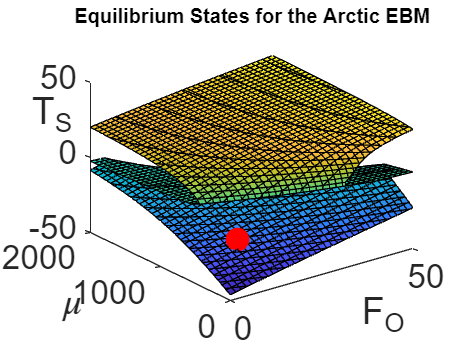

scatter3(9.75, 400, 273.15*presentclimArc-273.15 + 3, 'o', 'filled', 'markerfacecolor', 'r', 'SizeData', 200);
    view(-37.5,30);
    ax = gca;
    ax.FontSize = 20;
    xlabel('F_O', 'Position', [29.8512,-260.7302,-58.679]);
    ylabel('\mu', 'Position', [-14.006934895376613,1321.067298304937,-55.086570182702175]);
    zlabel('T_S', 'Rotation', 0, 'Position', [-9.042744169178377,2077.065004159464,15.769863158131557]);
    title('Equilibrium States for the Arctic EBM', 'FontSize', 12);
hold off

% Projection of equilibrium manifold onto F_O/mu plane
figure();
hold on
fimplicit3(@(x, y, z) EnergyBalanceModelArctic(z/273.15 + 1, x, 104, y, 0.6), [0, 50, 0, 2000, -46, 40], 'facealpha', 0.3, 'edgecolor', 'none');

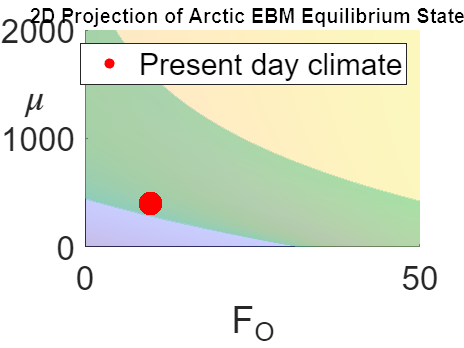

presclim = scatter3(9.75, 400, 50, 'o', 'filled', 'markerfacecolor', 'r', 'SizeData', 200);
    view(0,90);
    ax = gca;
    ax.FontSize = 20; 
    xlim([0, 50]);
    xlabel('F_O');
    ylabel('\mu', "Rotation", 0, 'Position', [-7.5824,1166.6,-46]);
    legend(presclim, 'Present day climate', 'Location', 'northeast');
    title('2D Projection of Arctic EBM Equilibrium States', 'FontSize', 12);
hold off

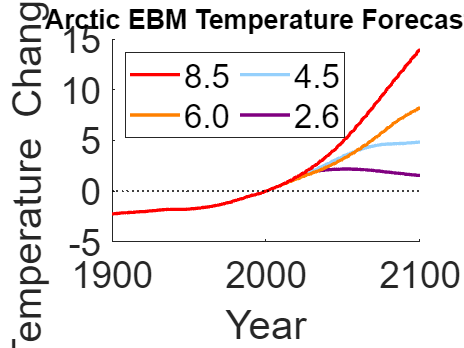

% Plot Arctic EBM temperature forecasts for SSP scenarios
figure();
clf
hold on 
%RCP2.6
RCP26 = fimplicit(@(x, y) EnergyBalanceModelArctic(y/273.15 + year2000tempArc, 9.75, 104, CO225data(round(x)-1764), 0.6), [1900, 2100, -5, 15], 'Color', [0.5,0,0.5], 'LineWidth', 2);  
%RCP4.5
RCP45 = fimplicit(@(x, y) EnergyBalanceModelArctic(y/273.15 + year2000tempArc, 9.75, 104, CO245data(round(x)-1764), 0.6), [1900, 2100, -5, 15], 'Color', [0.5843    0.8157    0.9882], 'LineWidth', 2);  
%RCP6.0
RCP60 = fimplicit(@(x, y) EnergyBalanceModelArctic(y/273.15 + year2000tempArc, 9.75, 104, CO260data(round(x)-1764), 0.6), [1900, 2100, -5, 15], 'Color', [1 0.5 0], 'LineWidth', 2);   
%RCP8.5
RCP85 = fimplicit(@(x, y) EnergyBalanceModelArctic(y/273.15 + year2000tempArc, 9.75, 104, CO285data(round(x)-1764), 0.6), [1900, 2100, -5, 15],'r', 'LineWidth', 2);
    x = [1900, 2100];    
    y = [0,0];
    plot(x,y,':k');           
    ax = gca;
    ax.FontSize = 22; 
    ylim([-5, 15]);
    lgd = legend([RCP85, RCP60, RCP45, RCP26], '8.5', '6.0', '4.5', '2.6', 'location', 'northwest');
    lgd.NumColumns = 2;
    ylabel('Temperature Change ^{\circ}C');
    xlabel('Year');
    title('Arctic EBM Temperature Forecasts', 'FontSize', 16);
hold off

% Get Arctic EBM forecasts for 2015-2100 and save as CSV
% This data is used in compare_esm_ebm_ssp585.ipynb to compare the ESM and
% EBM predictions
ssp585_temps = [];
for i=2015:1:2100
    fun = @(y) EnergyBalanceModelArctic(y/273.15 + year2000tempArc, 9.75, 104, CO285data(round(i)-1764), 0.6);
    ssp585_temps = [ssp585_temps, fsolve(fun, 5, options)];
end
ssp585_temps

ssp585_temps =     0.9855    1.0444    1.1326    1.2207    1.3087    1.3966    1.5008    1.5873    1.6737    1.7600    1.8461    1.9608    2.0466    2.1609    2.2464    2.3603    2.4455    2.5589    2.6721    2.7851    2.8979    3.0104    3.1227    3.2627    3.3745    3.4860    3.6250    3.7637    3.9021    4.0150    4.1519    4.3158    4.4519    4.5876    4.7499    4.9117    5.0461    5.2069    5.3671    5.5267    5.7122    5.8706    6.0000    6.2079    6.3895    6.5703    6.7503    6.9295    7.1080    7.2856


writematrix(ssp585_temps, 'arctic_ebm_ssp585_forecast.csv')

function F = EnergyBalanceModelArctic(tau, F_O, F_A, mu, delta)
% This function is the energy balance model for the Arctic region (70N)

% CONSTANTS
T_R = 273.15;                                   % K                     % reference temperature, equal to 0 Celcius
betaconst = 0.63;                               % nondimensional        % fraction of atmospheric irradiance hitting surface           
sigma = 5.670367*10^-8;                         % W/(m^2K^4)            % Stefan-Boltzmann constant 
omega = 0.01;                                   % nondimensional        % albedo switch function smoothness
Gamma = 6.49*10^-3;                             % K/m                   % standard ICAO lapse rate for the troposphere
gamma = Gamma/T_R;                              % 1/m                   % scaled lapse rate for non-dimensional system
k_C = 0.07424;                                  % m^2/kg                % absorption cross-section per unit mass of atmosphere for carbon dioxide
k_W = 0.05905;                                  % m^2/kg                % absorption cross-section per unit mass of atmosphere for water vapour
Z_P = 9000;                                     % m                     % troposphere height      
L_v = 2.2558*10^6;                              % m^2/s^2               % latent heat of vapourization for water
R = 8.3144598;                                  % J/(mol K)             % universal gas constant
R_W = 461.4;                                    % m^2/(s^2 K)           % specific gas constant of water vapour
alpha_w = 0.08;                                 % nondimensional        % warm (ocean) albedo
alpha_c = 0.7;                                  % nondimensional        % cold (ice) albedo
Q = 173.2;                                      % W/m^2                 % incoming solar radiation at 70N
q = Q/(sigma*T_R^4);                            % nondimensional        % scaled incoming solar radiation at 70N
c_P = 1004;                                     % J/(K kg)              % specific heat capacity of dry atmopshere at T_R
C_LH = 1.0*10^-3;                               % nondimensional        % latent heat bulk exchange coefficient 
C_SH = 1.0*10^-3;                               % nondimensional        % sensible heat bulk exchange coefficient
U_r = 4;                                        % m/s                   % average horizontal wind speed
z_r = 600;                                      % m                     % average height of planetary boundary layer
P_sat = 611.2;                                  % Pa = kg/(m s^2)       % saturated vapour pressure at T_R
rho_wsat = 4.849*10^-3;                         % kg/m^3                % saturated vapour density at T_R
P_0 = 101325.00;                                % Pa                    % pressure at surface 
M =  0.0289644;                                 % kg/mol                % molecular weight of dry air
G_W1 = L_v/(R_W*T_R);                           % nondimensional        % atmospheric water vapour absorption coefficient 1


% FUNCTIONS
T_S = tau*T_R;                                  % K                     % un-scaled surface temperature for use in SH and LH
% density of atmosphere (kg/m^3) at the top of PBL as a function of surface temperature
rho = P_0.*M./(R.*(T_S-Gamma.*z_r));                        
% vertical sensible heat transport (W/m^2) due to turbulent flux in the PBL
SH = c_P.*rho.*C_SH.*U_r.*(Gamma.*z_r);
% vertical latent heat transport (W/m^2) due to turbulent flux in the PBL
LE = L_v.*C_LH.*U_r./(R_W.*(T_S-Gamma.*z_r)).*P_sat.*(exp(G_W1.*(T_S - T_R)./T_S) - delta.*exp(G_W1.*(T_S - Gamma.*z_r -T_R)./(T_S - Gamma.*z_r)));
% combined vertical turbulent heat transport in the PBL
F_C = LE + SH;

f_A  = F_A./(sigma.*T_R.^4);                    % nondimensional        % scaled horizontal atmospheric heat transport
f_O  = F_O./(sigma.*T_R.^4);                    % nondimensional        % scaled horizontal aoceanic heat transport
f_C = F_C./(sigma.*T_R.^4);                     % nondimensional        % scaled vertical turbulent heat flux heat transport

% albedo switch function (nondimensional)
a = 1./2.*((alpha_w + alpha_c)+(alpha_w-alpha_c).*tanh((tau-1)./omega));    

eta_Cl = 0.3729;                                % nondimensional        % absorption due to clouds
G_c = 1.52./(10.^6).*k_C.*1.03.*10.^4;          % mol/micromol          % atmospheric carbon dioxide absorption coefficient
eta_C1 = 1 - exp(-G_c.*mu);                     % nondimensional        % absorption due to carbon dioxide         
G_W2 = k_W.*rho_wsat./gamma;                    % nondimensional        % atmospheric water vapour absorption coefficient 2
wvinteg1 = @(w) 1./w.*exp(G_W1.*(w-1)./w);      % nondimensional        % temperature-dependent part of Clausius-Clapeyron equation integrated over troposphere
eta_W1 = 1 - exp(-delta.*G_W2.*integral(wvinteg1, tau-(gamma.*Z_P), tau));   % nondimensional        % absorption due to water vapour     
eta = 1 - (1-eta_C1).*(1-eta_W1).*(1-eta_Cl);   % nondimensional        % total atmospheric longwave absorption

% entire energy balance model
F = (1-a).*q.*(1 - 0.2324 - 0.1212) + f_O - tau.^4 - f_C + betaconst.*(0.2324.*q + f_A + f_C + eta.*tau.^4);
end